# Create Building Animation

partFileXML = "building_with_solar_load.xml";
[apartment3D, geoLocation, dateTimeVec] = readBuildingDataXML(FileName=partFileXML);

viewingAngle = [-1 -1 1]; 

f  = figure("Name","Building Data");
p  = uipanel(f,"Position",[0.1 0.1 0.8 0.8],"BackgroundColor","w");
ax = axes(p);

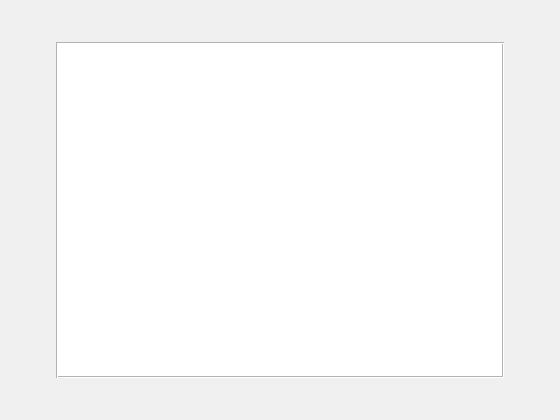

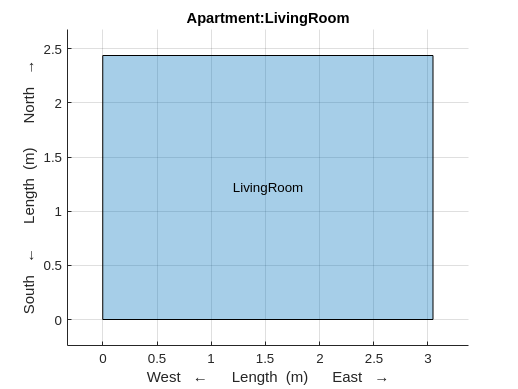

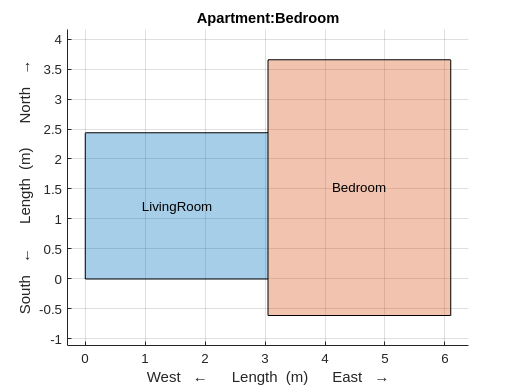

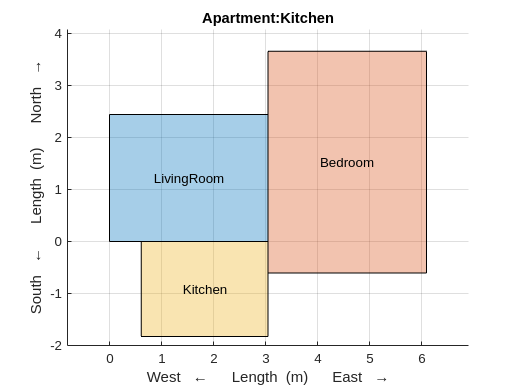

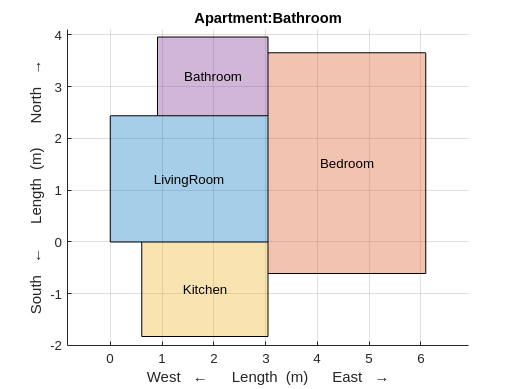

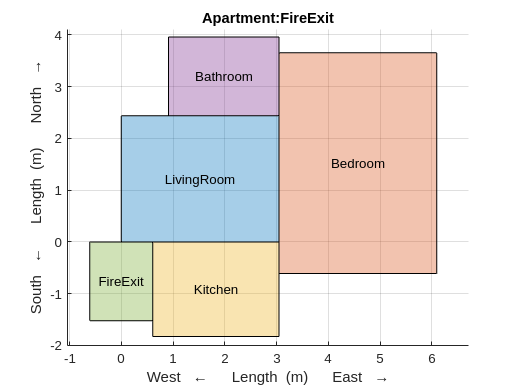

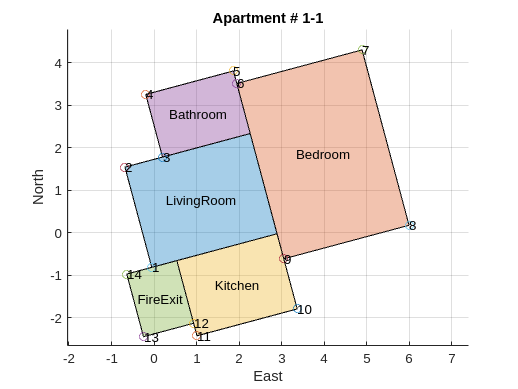

Use function addOpeningOnWallSection() to add windows or vent to the walls.


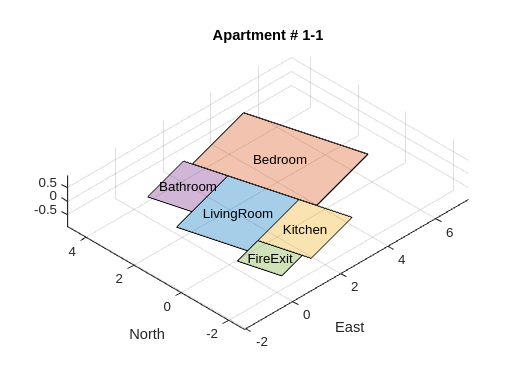

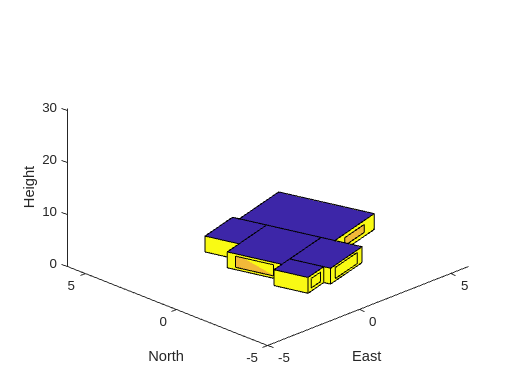

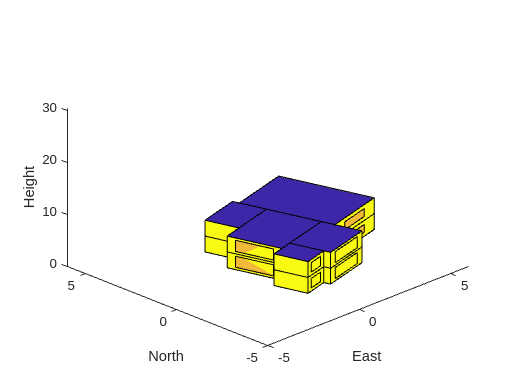

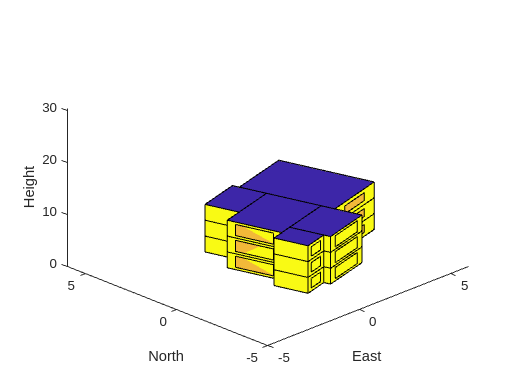

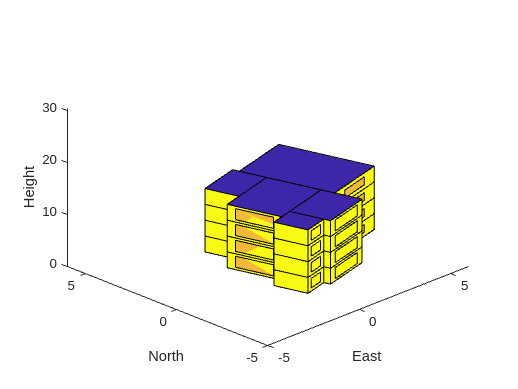

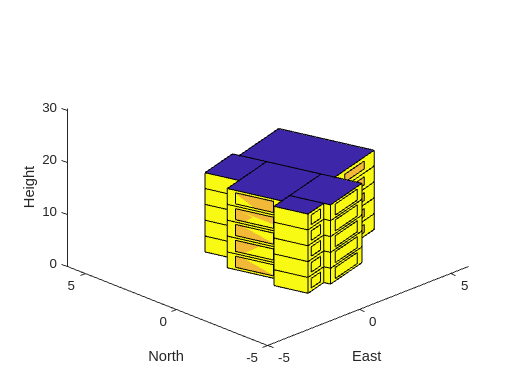

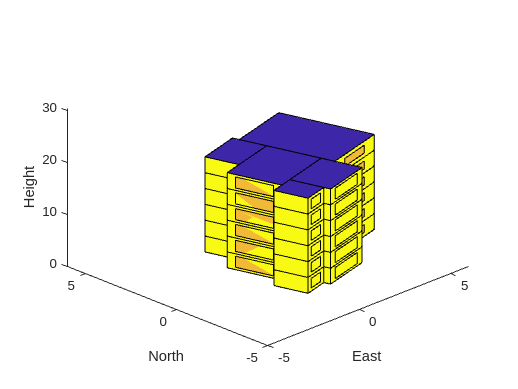

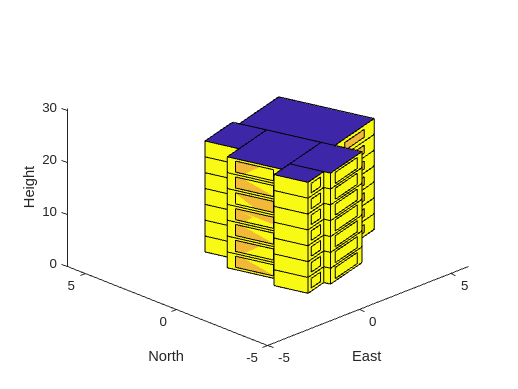

updateFreqHrs = 1;
for nHrs = 1:updateFreqHrs:length(dateTimeVec)
    plot3DlayoutBuilding(Building=apartment3D,PlotViewDirection=viewingAngle,...
        ColorScheme="radiation",Hour=nHrs);
    dateTimeVal = dateTimeVec(1,nHrs);
    colorbar("off");
    title(strcat('Sunlight (',geoLocation.Row,'), ',string(dateTimeVal)));
    recordAnimationData(1,nHrs) = getframe(gcf);
end

figure
axes("Position",[0 0 1 1])
movie(recordAnimationData,1,1)